# Gráficas tridimensionales

## Gráfica lineal tridimensional con función `plot3`

La función `plot3` es similar a la función `plot`, la diferencia radica en que esta nueva función recibe 3 vectores para realizar la gráfica en 3 dimensiones.

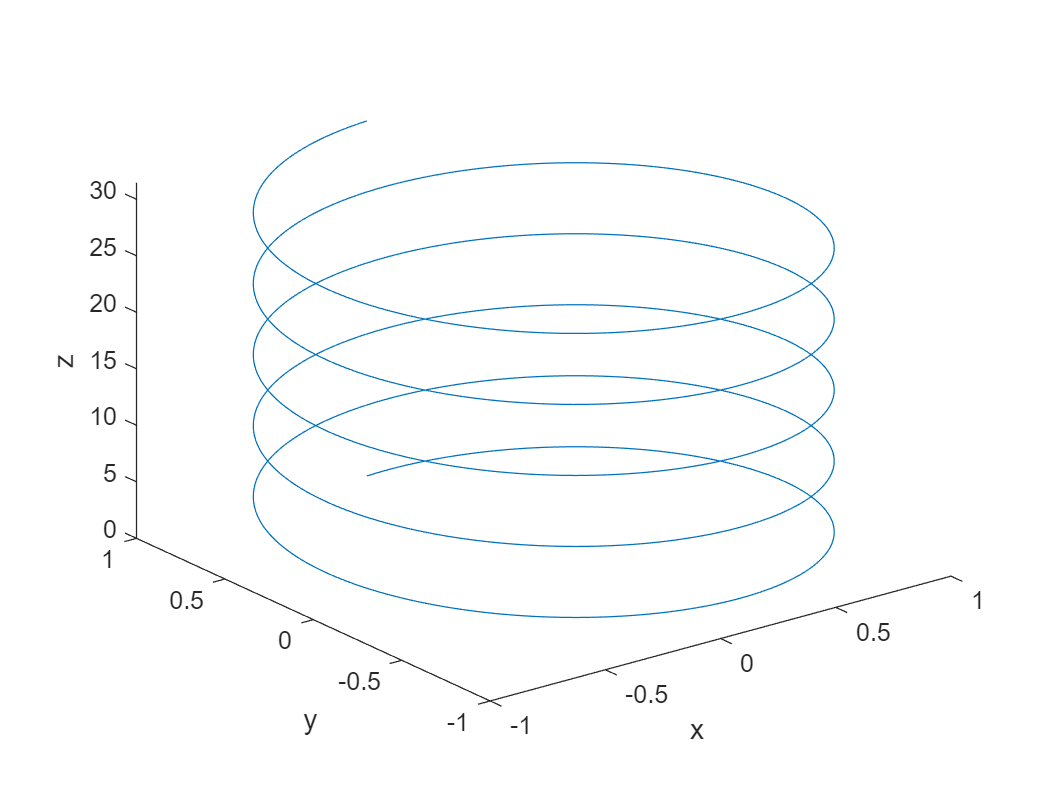

clear
t = linspace(0, 10*pi, 1000);
st = sin(t);
ct = cos(t);

plot3(st, ct, t)
xlabel x
ylabel y
zlabel z

Como se observa en el código, se puede modificar las mismas características para que la función `plot`, añadiéndose la posibilidad de editar también el eje **z**.

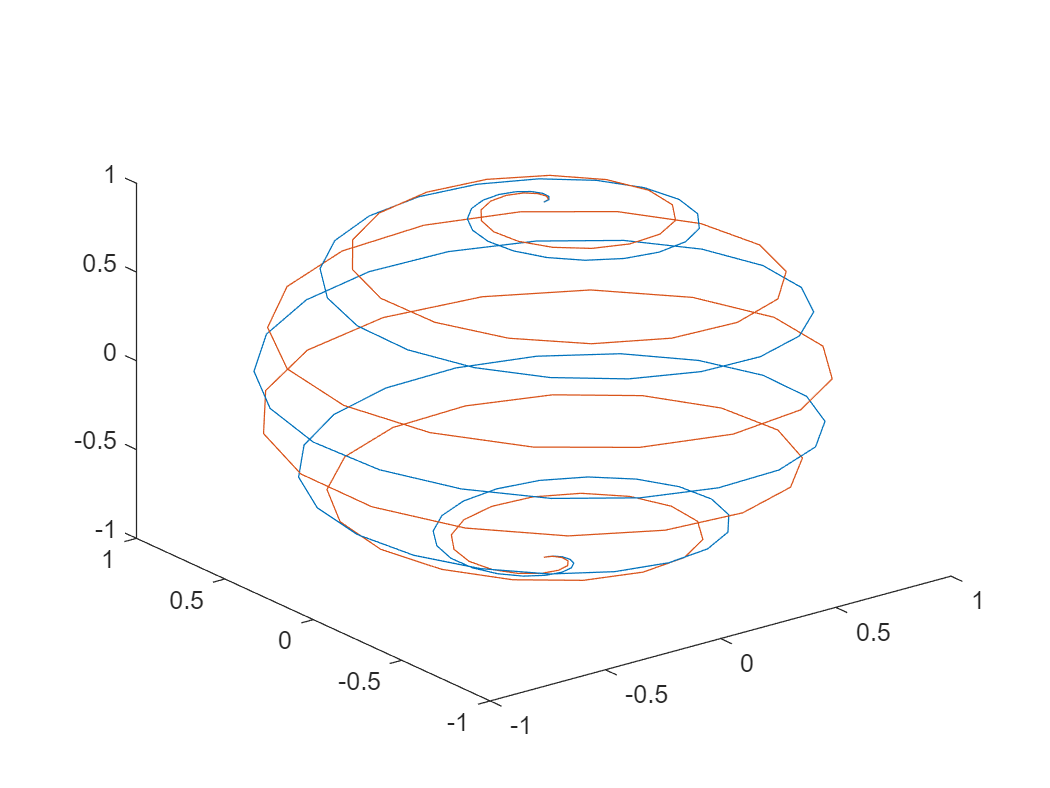

clear
t = 0:pi/100:pi;
xt1 = sin(t).*cos(10*t);
yt1 = sin(t).*sin(10*t);
zt1 = cos(t);

xt2 = sin(t).*cos(12*t);
yt2 = sin(t).*sin(12*t);
zt2 = cos(t);

plot3(xt1, yt1, zt2)
hold on
plot3(xt2, yt2, zt2)
hold off

**Nota:** La función `plot3` utiliza la regla de la mano derecha para generar el sistema de coordenadas.

### Función `comet3`

Una función curiosa es la `comet3`. Esta función genera la misma gráfica que la función `plot3`, pero la va "dibujando" en lugar de presentarla graficada en su totalidad.

comet3(xt1, yt1, zt2)
hold on
comet3(xt2, yt2, zt2)
hold off

**Nota:** Para gráficas bidimensionales se utiliza la función `comet`.

### Gráficas de superficie

Las gráficas de superficie permiten representar datos como una superficie.

#### Gráficas `mesh`

Existen muchas formas de usar las gráficas de malla (`mesh`). Por ejemplo, se pueden utilizar para dar un buen efecto a una matriz bidimensional sencilla `mxn`. En esta aplicación, el valor de la matriz representa los valores para de **z** en la gráfica.

Para esta, y muchas otras aplicaciones, se utiliza la función `mesh`.

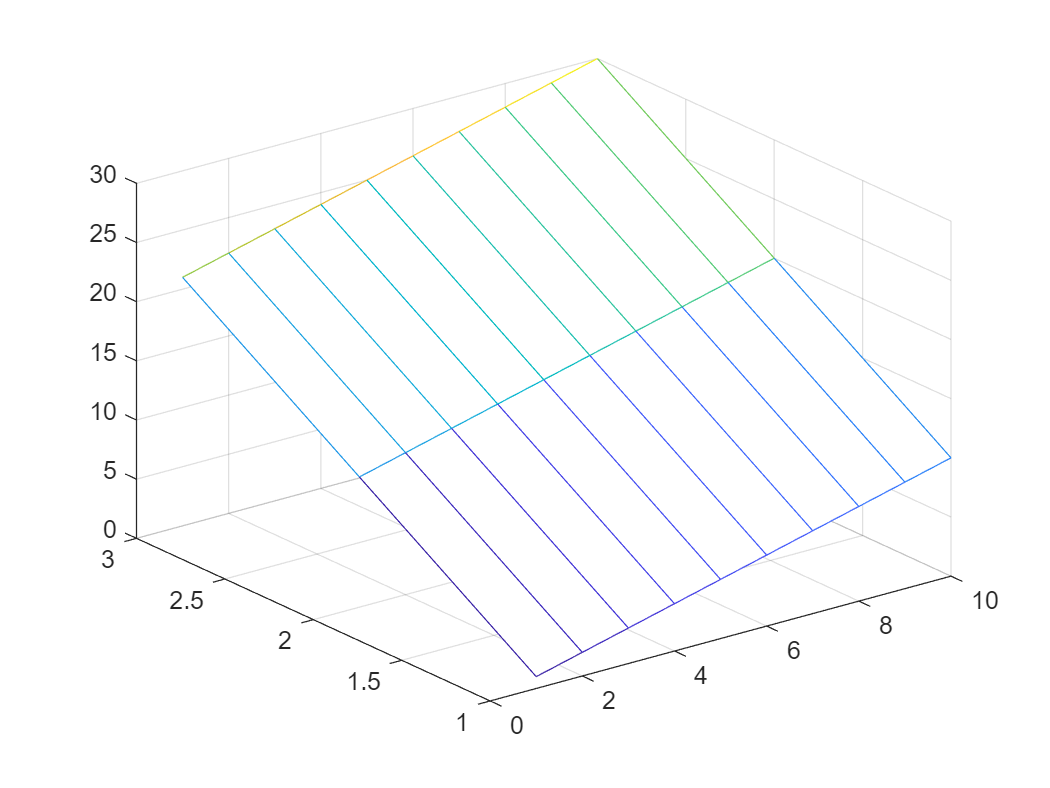

A = [1:10
     11:20
     21:30];
mesh(A)

Como ya se dijo, la gráfica es una malla creada a partir de la matriz `z`. Pero, ¿de dónde toma los valores representar **x** y **y**? Pues bien, si sólo se ingresa un argumento a la función `mesh`,

- **x** tomará como valores los índices de las columnas, es decir, para graficar `z` se tomó **x** = `1:10` (número de columnas de `z`).

- **y** tomará como valores los índices de las filas, es decir, para graficar `z` se tomó **y** = `1:3` (número de filas de `z`).

Entonces, para graficar el elemento en la posición $z_{1,5}=5$ el punto graficado es $P(x,y,z)=(5,1,5)$.

Sin embargo, también se le puede pasar a la función 3 argumentos que serían los vectores **x**, **y** y **z**.

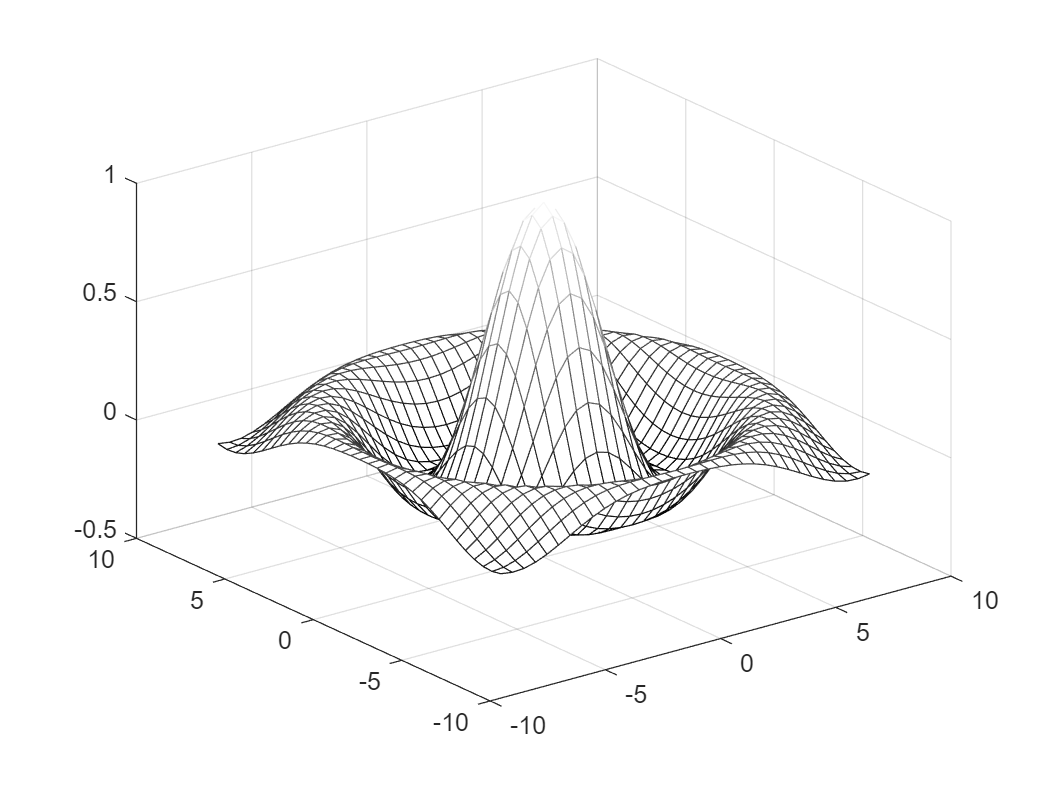

[X,Y] = meshgrid(-8:.5:8);
R = sqrt(X.^2 + Y.^2) + eps;
Z = sin(R)./R;
mesh(X,Y,Z)

Se debe tener en cuenta las siguientes consideraciones cuando se ingresan los 3 argumentos a la función `mesh`:

- El vector **x** debe tener el mismo número de elementos que el número de columnas en el vector **z**.

- El vector **y** debe tener el mismo número de elementos que el número de filas en el vector **z**.

#### Gráficas `surf`

Las gráficas `surf` son similares a las gráficas `mesh`, pero `surf` crea una superficie tridimensional colorida en lugar de una malla. Los colores varían con el valor de **z**.

Las mismas consideraciones que se hicieron para la funcion `mesh` cuando se ingresa un solo argumento, o varios, son válidas para la función `surf`.

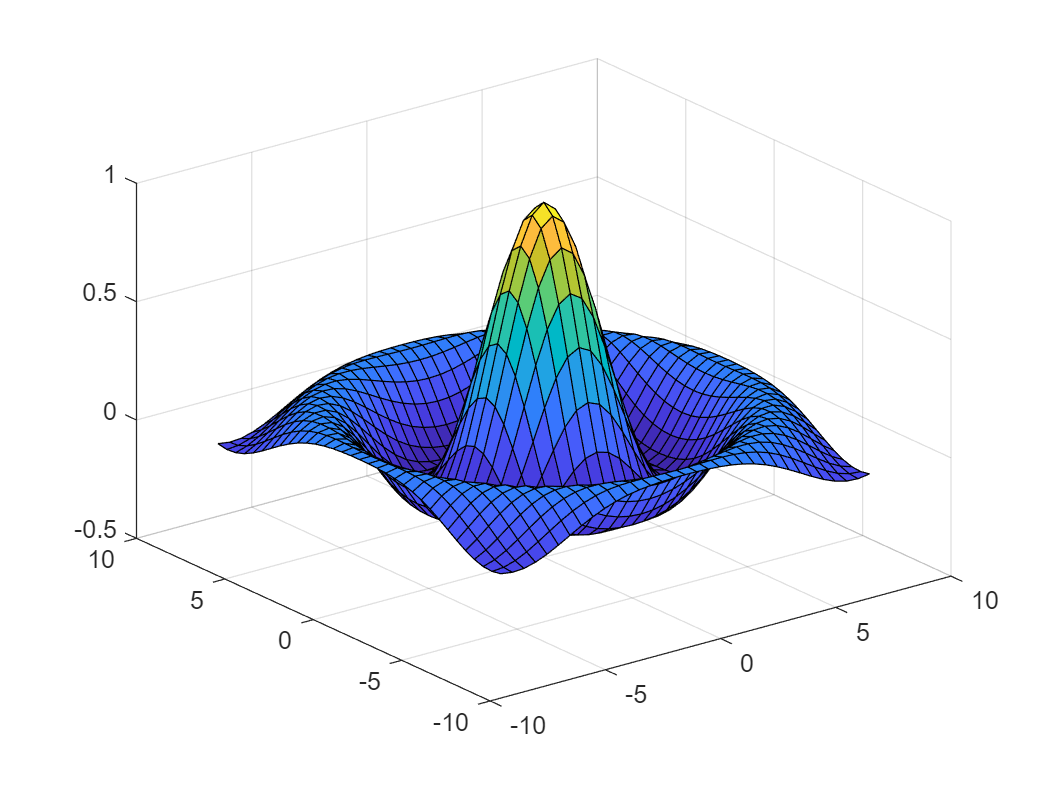

surf(X, Y, Z)

#### Comando `shading`

El comando `shading` controla el sombreado de una gráfica. Existen 3 tipos de sobreado: `faceted` (por defecto), `flat` e `interp`.

El sombreado `interp` interpola valores de **z** para crear una gama de colores.

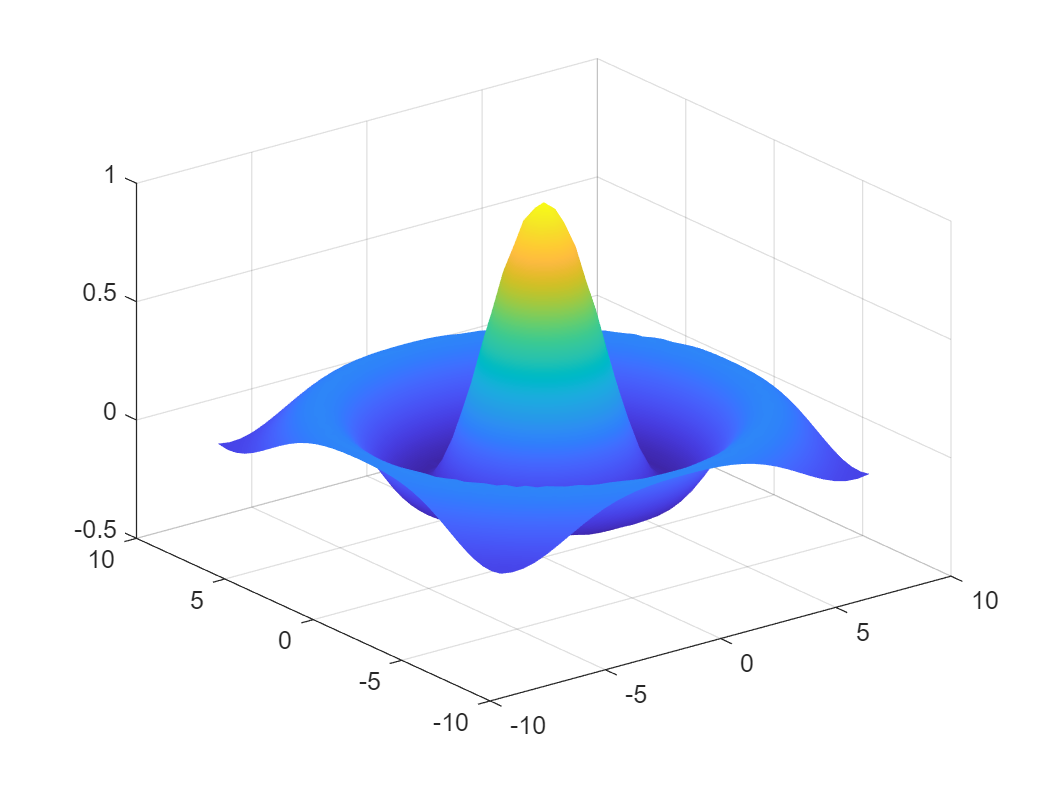

shading interp

El sobreado `flat` genera un sombreado plano sin retícula.

% Su código va aquí :)

#### Comando `colormap`

El comando `colormap` controla el esquema de color usado en la gráfica.

surf(X, Y, Z)
colormap gray 

A continuación se muestran los colores disponibles: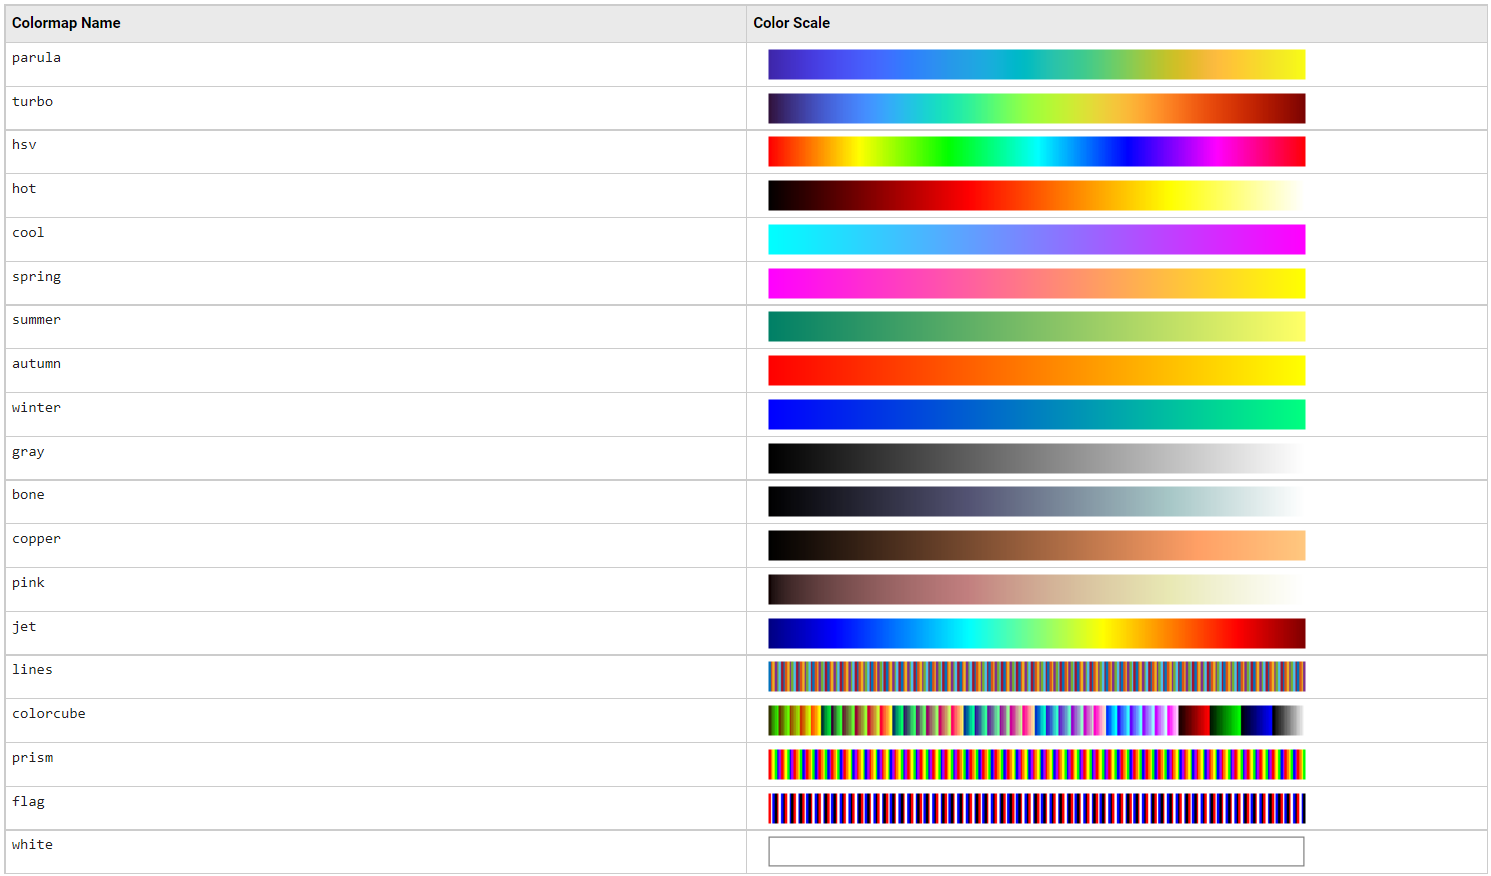

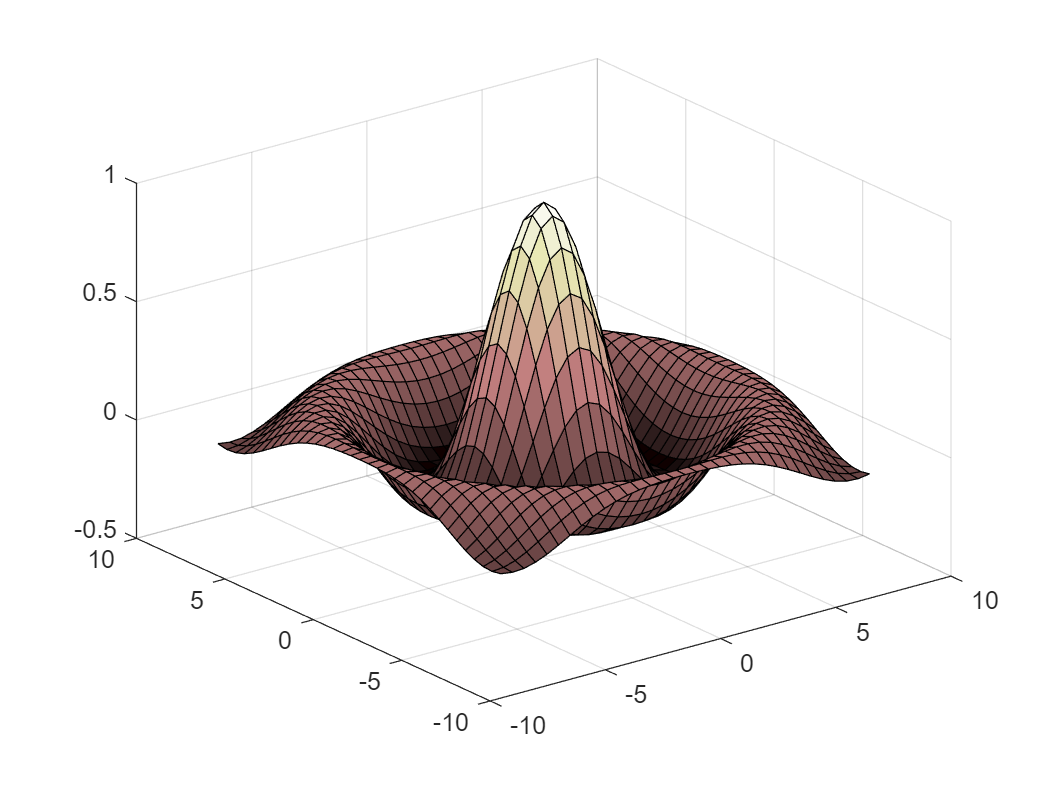

colormap pink

### Gráficas de contorno

Las gráficas de contorno son representaciones bidiomensionales de superficies tridimensionales. Ejemplo: curvas de nivel.

Mediante la función `contour` se las puede generar.

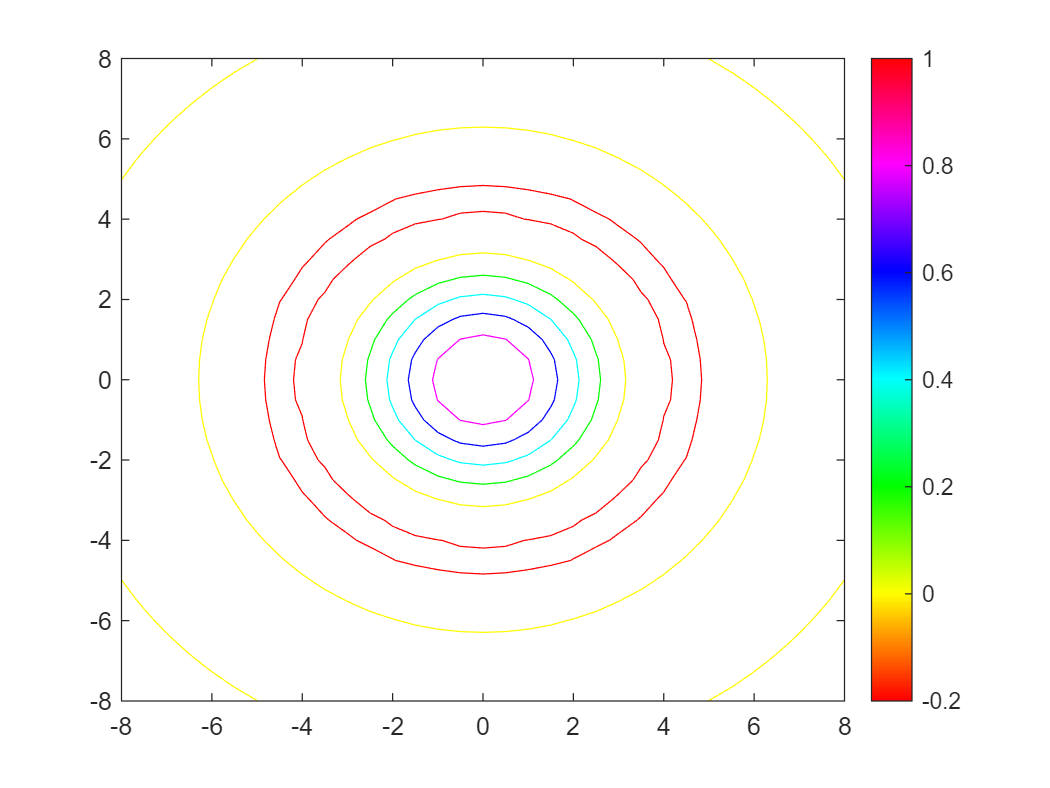

contour(X, Y, Z)
colormap hsv
colorbar

La función `surfc` genera una gráfica de superficie y de contorno al mismo tiempo.

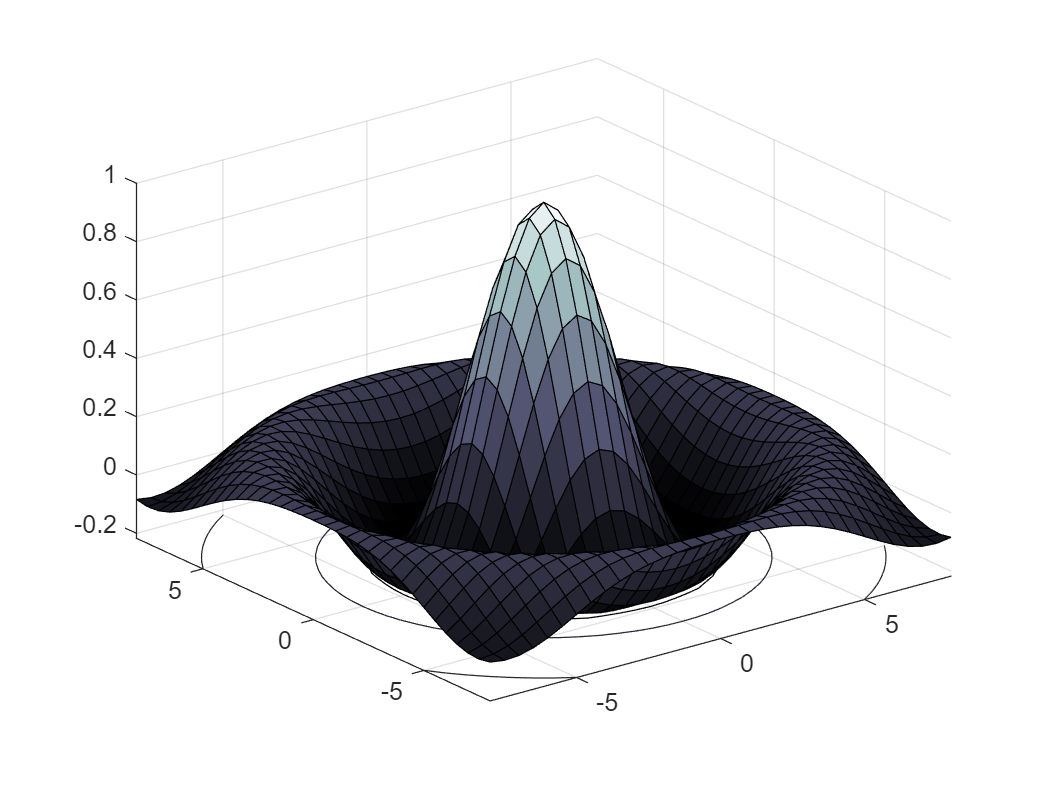

surfc(X, Y, Z)
colormap bone

### Gráficas en pseudocolor

Las gráficas en pseudocolor son similares a las gráficas de contorno, excepto que, en lugar de líneas que resaltan un contorno específico, se genera un mapa bidimensional sombreado sobre una retícula.

MATLAB incluye una función muestra llamada `peaks` (detallada en el subcapítulo 1: **sc1**) que genera las matrices **x**, **y** y **z** de una interesante superficie que parece una montaña.

La función `pcolor` genera este tipo de gráficas.

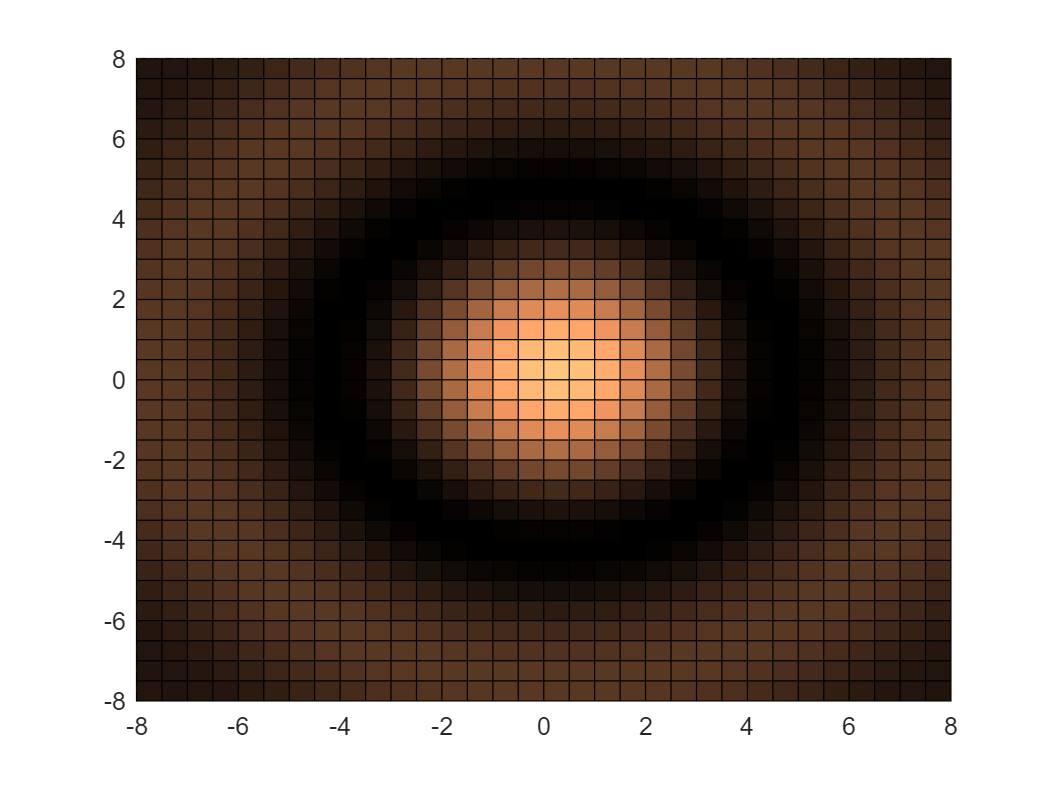

pcolor(X, Y, Z)
colormap copper